# Analyze Steady-State Community COBRA Models at  Using SteadyCom

## Author(s): Siu Hung Joshua Chan, Department of Chemical Engineering, The Pennsylvania State University

## Reviewer(s): 

## INTRODUCTION

This tutorial demonstrates the use of SteadyCom to analyze a multi-organism COBRA model (e.g., for a microbial community) at a community steady-state [1]. Compared to the direct extension of flux balance analysis (FBA) which simply treats a community model as a multi-compartment model, SteadyCom explicitly introduces the biomass variables to describe the relationships between biomass, biomass production rate, growth rate and fluxes. SteadyCom also assumes the existence of a time-averaged population steady-state for a stable microbial community which in turn implies a time-averaged constant growth rate across all members. SteadyCom is equivalent to the reformulation of the earlier community flux balance analysis (cFBA) [2] with significant computational advantage. SteadyCom computes the maximum community growth rate by solving the follow optimization problem:


$$\begin{array}{ll}
\max & \ \mu\\ \\
\text{s.t.} & \sum\limits_{j\in \textbf{J}^k}S^k_{ij}V^k_j=0, & \forall i \in \textbf{I}^k, k \in \textbf{K}\\
 & LB^k_jX^k\leq V^k_j\leq UB^k_jX^k, & \forall j \in \textbf{J}^k, k \in \textbf{K} \\
& \sum\limits_{k \in \textbf{K}}V^k_{ex(i)} + u^{com}_i\geq 0, & \forall i \in \textbf{I}^{com} \\
& V^k_{biomass} = X^k\mu, & \forall k \in \textbf{K} \\
& \sum\limits_{k \in \textbf{K}}X^k = 1 \\
& X^k,\quad \mu \geq 0, & \forall k \in \textbf{K} \\
& V^k_j \in \Re, & \forall j \in \textbf{J}^k, k \in \textbf{K} 
\end{array}$$


where $S^k_{ij}$ is the stoichiometry of metabolite *i* in reaction *j* for organism *k*, $V^k_j$, $LB^k_j$ and $UB^k_j$ are respectively the flux (in mmol/h), lower bound (in mmol/h/gdw) and upper bound (in mmol/h/gdw) for reaction *j* for organism *k*, $u^{com}_i$ is the community uptake bound for metabolite *i*, $X^k$ is the biomass (in gdw) of organism *k*, $\mu$ is the community growth rate, $\textbf{I}^k$ is the set of metabolites of organism *k*, $\textbf{I}^{com}$ is the set of community metabolites in the community exchange space, $\textbf{J}^k$ is the set of reactions for organism k, $\textbf{K}$ is the set of organisms in the community, and $ex(i) \in \textbf{J}^k$ is the exchange reaction in organism *k* for extracellular metabolite *i*. See ref. [1] for the derivation and detailed explanation.

Throughout the tutorial, using a hypothetical model of four *E. coli* mutants auxotrophic for amino acids, we will demonstrate the three different functionalities of the module: (1) computing the maximum community growth rate using the function SteadyCom.m, (2) performing flux variability analysis under a given community growth rate using SteadyComFVA.m, and (3) analyzing the pairwise relationship between flux/biomass variables using a technique similar to Pareto-optimal analysis by calling the function SteadyComPOA.m

## EQUIPMENT SETUP

If necessary, initialise the cobra toolbox and select a solver by running:

initCobraToolbox



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2017
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done.
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules ... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > Retrieving models ...   Done.
 > TranslateSBML is installed and working properly.
 > Configuring sol

All SteadyCom functions involve only solving linear programming problems. Any solvers supported by the COBRA toolbox will work. But SteadyCom contains specialized codes for IBM ILOG Cplex which was tested to run significantly faster for SteadyComFVA and SteadyComPOA for larger problems through calling the Cplex object in Matlab directly.

changeCobraSolver('ibm_cplex', 'LP');

## PROCEDURE

## Model Construction

Load the *E. coli* iAF1260 model in the COBRA toolbox:

load('iAF1260.mat', 'iAF1260');

Polish the model a little bit:

% convert the compartment format from e.g., '_c' to '[c]'
iAF1260.mets = regexprep(iAF1260.mets, '_([^_]+)$', '\[$1\]');
% make all empty cells in cell arrays to be empty string
fieldToBeCellStr = {'metFormulas'; 'genes'; 'grRules'; 'metNames'; 'rxnNames'; 'subSystems'};
for j = 1:numel(fieldToBeCellStr)
    iAF1260.(fieldToBeCellStr{j})(cellfun(@isempty, iAF1260.(fieldToBeCellStr{j}))) = {''};
end

Add a methionine export reaction to allow the export of methionine.

iAF1260 = addReaction(iAF1260,{'METt3pp',''},'met__L[c] + h[c] => met__L[p] + h[p]');

METt3pp	h[c] + met__L[c] 	->	h[p] + met__L[p] 


Reactions essential for amino acid autotrophy:

argH = {'ARGSL'};  % essential for arginine biosynthesis
lysA = {'DAPDC'};  % essential for lysine biosynthesis
metA = {'HSST'};  % essential for methionine biosynthesis
ilvE = {'PPNDH'};  % essential for phenylalanine biosynthesis

Reactions essential for exporting amino acids:

argO = {'ARGt3pp'};  % Evidence for an arginine exporter encoded by yggA (argO) that is regulated by the LysR-type transcriptional regulator ArgP in Escherichia coli.
lysO = {'LYSt3pp'};  % Distinct paths for basic amino acid export in Escherichia coli: YbjE (LysO) mediates export of L-lysine
yjeH = {'METt3pp'};  % YjeH is a novel L-methionine and branched chain amino acids exporter in Escherichia coli
yddG = {'PHEt2rpp'};  % YddG from Escherichia coli promotes export of aromatic amino acids.

Now make four copies of the model with auxotrophy for different amino acids and inability to export amino acids:

% auxotrophic for Lys and Met, not exporting Phe
Ec1 = iAF1260;
Ec1 = changeRxnBounds(Ec1, [lysA; metA; yddG], 0, 'b');
% auxotrophic for Arg and Phe, not exporting Met
Ec2 = iAF1260;
Ec2 = changeRxnBounds(Ec2, [argH; yjeH; ilvE], 0, 'b');
% Auxotrophic for Arg and Phe, not exporting Lys
Ec3 = iAF1260;
Ec3 = changeRxnBounds(Ec3, [argH; lysO; ilvE], 0, 'b');
% Auxotrophic for Lys and Met, not exporting Arg
Ec4 = iAF1260;
Ec4 = changeRxnBounds(Ec4, [argO; lysA; metA], 0, 'b');

Now none of the four organisms can grow alone and they must cross feed each other to survive. See Figure 1 in ref. [[1]](http://journals.plos.org/ploscompbiol/article?id=10.1371/journal.pcbi.1005539) for the visualization of the community. 

Get the extracellular metabolites, the corresponding exchange reactions and the uptake rates for the *E. coli* model, which are used later to constrain the community model:

% extracellular metabolites (met[e])
metEx = strcmp(getCompartment(iAF1260.mets),'e');
% the corresponding exchange reactions
rxnExAll = find(sum(iAF1260.S ~= 0, 1) == 1);
[rxnEx, ~] = find(iAF1260.S(metEx, rxnExAll)');  % need to be in the same order as metEx
rxnEx = rxnExAll(rxnEx);
% exchange rate
lbEx = iAF1260.lb(rxnEx);

Create a community model with the four *E. coli* tagged as 'Ec1', 'Ec2', 'Ec3', 'Ec4' respectively by calling `createMultipleSpeciesModel`. 

nameTagsModel = {'Ec1'; 'Ec2'; 'Ec3'; 'Ec4'};
EcCom = createMultipleSpeciesModel({Ec1; Ec2; Ec3; Ec4}, nameTagsModel);

The following fields are missing in several models, they will not be merged:
Ec1IEX_12ppd__R[u]tr	Ec112ppd__R[e] 	<=>	12ppd__R[u] 
Ec1IEX_12ppd__S[u]tr	Ec112ppd__S[e] 	<=>	12ppd__S[u] 
Ec1IEX_14glucan[u]tr	Ec114glucan[e] 	<=>	14glucan[u] 
Ec1IEX_15dap[u]tr	Ec115dap[e] 	<=>	15dap[u] 
Ec1IEX_23camp[u]tr	Ec123camp[e] 	<=>	23camp[u] 
Ec1IEX_23ccmp[u]tr	Ec123ccmp[e] 	<=>	23ccmp[u] 
Ec1IEX_23cgmp[u]tr	Ec123cgmp[e] 	<=>	23cgmp[u] 
Ec1IEX_23cump[u]tr	Ec123cump[e] 	<=>	23cump[u] 
Ec1IEX_23dappa[u]tr	Ec123dappa[e] 	<=>	23dappa[u] 
Ec1IEX_26dap__M[u]tr	Ec126dap__M[e] 	<=>	26dap__M[u] 
Ec1IEX_2ddglcn[u]tr	Ec12ddglcn[e] 	<=>	2ddglcn[u] 
Ec1IEX_34dhpac[u]tr	Ec134dhpac[e] 	<=>	34dhpac[u] 
Ec1IEX_3amp[u]tr	Ec13amp[e] 	<=>	3amp[u] 
Ec1IEX_3cmp[u]tr	Ec13cmp[e] 	<=>	3cmp[u] 
Ec1IEX_3gmp[u]tr	Ec13gmp[e] 	<=>	3gmp[u] 
Ec1IEX_3hcinnm[u]tr	Ec13hcinnm[e] 	<=>	3hcinnm[u] 
Ec1IEX_3hpppn[u]tr	Ec13hpppn[e] 	<=>	3hpppn[u] 
Ec1IEX_3ump[u]tr	Ec13ump[e] 	<=>	3ump[u] 
Ec1IEX_4abut[u]tr	Ec14abut[e] 	<=>	4abut[u] 
Ec1IE

EcCom.csense = char('E' * ones(1,numel(EcCom.mets)));  % correct the csense
clear Ec1 Ec2 Ec3 Ec4

The model `EcCom` contains a community compartment denoted by `[u]` to allow exchange between organisms. Each organism-specific reaction/metabolite is prepended with the corresponding tag.

Retreive the names and ids for organism/community exchange reactions/metabolites which are necessary for computation:

[EcCom.infoCom, EcCom.indCom] = getMultiSpeciesModelId(EcCom, nameTagsModel);
disp(EcCom.infoCom);

    spAbbr: {4×1 cell}
    spName: {4×1 cell}
     EXcom: {299×1 cell}
    EXhost: {0×1 cell}
      EXsp: {299×4 cell}
      Mcom: {299×1 cell}
     Mhost: {0×1 cell}
       Msp: {299×4 cell}
    rxnSps: {9831×1 cell}
    metSps: {6971×1 cell}


`EcCom.infoCom `contains reaction/metabolite names (from `EcCom.rxns`/`EcCom.mets`) for the community exchange reactions (`*.EXcom`), organism-community exchange reactions (`*.EXsp`), community metabolites (`*.Mcom`), organism-specific extracellular metabolite (`*.Msp`). If a host model is specified, there will also be non-empty `*.EXhost` and `*.Mhost `for the host-specific exchange reactions and metabolites. The fields `*.rxnSps`/`*.metSps` give information on which organism a reaction/metabolite belongs to.

`indCom `has the same structure as `infoCom` but contains the indices rather than names. `infoCom` and `indCom` are attached as fields of the model `EcCom` because SteadyCom requires this information from the input model for computation. Incorporate also the names and indices for the biomass reactions which are necessary for computing growth:

rxnBiomass = strcat(nameTagsModel, 'BIOMASS_Ec_iAF1260_core_59p81M');  % biomass reaction names
rxnBiomassId = findRxnIDs(EcCom, rxnBiomass);  % ids
EcCom.infoCom.spBm = rxnBiomass;  % .spBm for organism biomass reactions
EcCom.indCom.spBm = rxnBiomassId;

## Finding Maximum Growth Rate Using SteadyCom

Set community and organism-specific uptake rates to be the same as in the orginal iAF1260 model:

[yn, id] = ismember(strrep(iAF1260.mets(metEx), '[e]', '[u]'), EcCom.infoCom.Mcom);  % map the metabolite name
assert(all(yn));  % must be a 1-to-1 mapping
EcCom.lb(EcCom.indCom.EXcom(:,1)) = lbEx(id);  % assign community uptake bounds
EcCom.ub(EcCom.indCom.EXcom(:,1)) = 1e5;
EcCom.lb(EcCom.indCom.EXsp) = repmat(lbEx(id), 1, 4);  % assign organism-specific uptake bounds

Set maximum allowed organism-specific uptake rates for the cross-feeding amino acids:

% only allow to take up the amino acids that one is auxotrophic for
exRate = 1;  % maximum uptake rate for cross feeding AAs
% Ec1
EcCom = changeRxnBounds(EcCom, {'Ec1IEX_arg__L[u]tr'; 'Ec1IEX_phe__L[u]tr'}, 0, 'l');
EcCom = changeRxnBounds(EcCom, {'Ec1IEX_met__L[u]tr'; 'Ec1IEX_lys__L[u]tr'}, -exRate, 'l');
% Ec2
EcCom = changeRxnBounds(EcCom, {'Ec2IEX_arg__L[u]tr'; 'Ec2IEX_phe__L[u]tr'}, -exRate, 'l');
EcCom = changeRxnBounds(EcCom, {'Ec2IEX_met__L[u]tr'; 'Ec2IEX_lys__L[u]tr'}, 0, 'l');
% Ec3
EcCom = changeRxnBounds(EcCom, {'Ec3IEX_arg__L[u]tr'; 'Ec3IEX_phe__L[u]tr'}, -exRate, 'l');
EcCom = changeRxnBounds(EcCom, {'Ec3IEX_met__L[u]tr'; 'Ec3IEX_lys__L[u]tr'}, 0, 'l');
% Ec4
EcCom = changeRxnBounds(EcCom, {'Ec4IEX_arg__L[u]tr'; 'Ec4IEX_phe__L[u]tr'}, 0, 'l');
EcCom = changeRxnBounds(EcCom, {'Ec4IEX_met__L[u]tr'; 'Ec4IEX_lys__L[u]tr'}, -exRate, 'l');
% allow production of anything for each member
EcCom.ub(EcCom.indCom.EXsp(:)) = 1000;

Before the calculation, print the community uptake bounds for checking using `printUptakeBoundCom`:

printUptakeBoundCom(EcCom, 1);

         Mets	Comm.     Ec1       Ec2       Ec3       Ec4       
 ( 53) arg__L	0         0         -1        -1        0         
    ( 60) ca2	1e+06     -1e+06    -1e+06    -1e+06    -1e+06    
   ( 62) cbl1	0.01      -0.01     -0.01     -0.01     -0.01     
     ( 67) cl	1e+06     -1e+06    -1e+06    -1e+06    -1e+06    
    ( 69) co2	1e+06     -1e+06    -1e+06    -1e+06    -1e+06    
( 70) cobalt2	1e+06     -1e+06    -1e+06    -1e+06    -1e+06    
    ( 76) cu2	1e+06     -1e+06    -1e+06    -1e+06    -1e+06    
    (108) fe2	1e+06     -1e+06    -1e+06    -1e+06    -1e+06    
    (109) fe3	1e+06     -1e+06    -1e+06    -1e+06    -1e+06    
 (144) glc__D	8         -8        -8        -8        -8        
    (167) h2o	1e+06     -1e+06    -1e+06    -1e+06    -1e+06    
      (169) h	1e+06     -1e+06    -1e+06    -1e+06    -1e+06    
      (186) k	1e+06     -1e+06    -1e+06    -1e+06    -1e+06    
 (194) lys__L	0         -1        0         0         -1        
 (208) met__L	0         -

Values under 'Comm.' are the community uptake bounds (+ve for uptake) and values under 'Ec1' are the Ec1-specific uptake bounds (-ve for uptake). 

Create an option structure for calling SteadyCom and call the function. There are a range of options available, including setting algorithmic parameters, fixing growth rates for members, adding additional linear constraints in a general format, e.g., for molecular crowding effect. See `help SteadyCom `for more options.

options = struct();
options.GRguess = 0.5;  % initial guess for max. growth rate
options.GRtol = 1e-6;  % tolerance for final growth rate
options.algorithm = 1;  % use the default algorithm (simple guessing for bounds, followed by matlab fzero)
[sol, result] = SteadyCom(EcCom, options);

Find maximum community growth rate..
Model feasible at maintenance. Time elapsed: 1 / 1 sec
Iter        LB   To test        UB  Time elapsed (iteration/total)
   1  0.000000  0.500000       Inf  0 / 1 sec
   2  0.500000  0.721279       Inf  6 / 7 sec
   3  0.721279  0.735372       Inf  0 / 8 sec
   4  0.735372  0.742726       Inf  0 / 8 sec
 
 Func-count    x          f(x)             Procedure
    2        0.735372  -0.000807615        initial
    3        0.735378   -0.00079987        interpolation
    4         0.73599  -1.26398e-06        interpolation
    5         0.73599  -1.26398e-06        interpolation
 
Zero found in the interval [0.735372, 0.742726]
Maximum community growth rate: 0.735990 (abs. error < 1e-06).	Time elapsed: 18 sec


The algorithm is an iterative procedure to find the maximum biomass at a given growth rate and to determine the maximum growth rate that is feasible for the required total biomass (default 1 gdw). Here the algorithm used is the simple guessing for find upper and lower bounds (Iter 1 to 4 in the output) followed by Matlab `fzero` (starting from the line '`Func-count`') to locate the root. The maximum growth rate calculated is 0.73599 /h, stored in `result.GRmax`. 

The biomass for each organism (in gdw) is given by `result.BM`:

for jSp = 1:4
    fprintf('X_%s:  %.6f\n', EcCom.infoCom.spAbbr{jSp}, result.BM(jSp));
end

X_Ec1:  0.253294


X_Ec2:  0.324611


X_Ec3:  0.185004


X_Ec4:  0.237093


disp(result);

    GRmax: 0.7360
      vBM: [4×1 double]
       BM: [4×1 double]
       Ut: [299×1 double]
       Ex: [299×1 double]
     flux: [9831×1 double]
    iter0: [0 11.4198 0 9.9476e-14]
     iter: [4×6 double]
     stat: 'optimal'


`result.vBM` contains the biomass production rates (in gdw / h), equal to `result.BM * result.GRmax. `Since the total community biomass is defaulted to be 1 gdw, the biomass for each organism coincides with its relative abundance. Note that the community uptake bounds in this sense are normalized per gdw of the community biomass. So the lower bound for the exchange reaction `EX_glc__D[u]` being 8 can be interpreted as the maximum amount of glucose available to the community being at a rate of 8 mmol per hour for 1 gdw of community biomass. Similarly, all fluxes in `result.flux `($V^k_j$) has the unit mmol / h / [gdw of comm. biomass]. It differs from the specific rate (traditionally denoted by $v^k_j$) of an organism in the usual sense (in the unit of mmol / h / [gdw of organism biomass]) by $V^k_j=X^kv^k_j$ where $X^k$ is the biomass of the organism. `result.Ut` and `result.Ex `are the community uptake and export rates respectively, corresponding to the exchange reactions in `EcCom.infoCom.EXcom`. 

`result.iter0 `is the info for solving the model at zero growth rate and `result.iter `records the info during iteration of the algorithm:


iter = [0, result.iter0, NaN; result.iter];
for j = 0 : size(iter, 1)
    if j == 0
        fprintf('#iter\tgrowth rate (mu)\tmax. biomass (sum(X))\tmu * sum(X)\tmax. infeasibility\tguess method\n');
    else
        fprintf('%5d\t%16.6f\t%21.6f\t%11.6f\t%18.6e\t%d\n', iter(j,:))
    end
end

#iter	growth rate (mu)	max. biomass (sum(X))	mu * sum(X)	max. infeasibility	guess method


    0	        0.000000	            11.419845	   0.000000	      9.947598e-14	NaN


    1	        0.500000	             1.442559	   0.721279	      5.555648e-10	0


    2	        0.721279	             1.019539	   0.735372	      3.778331e-10	0


    3	        0.735372	             1.000808	   0.735966	      7.999141e-11	0


    4	        0.742726	             0.000000	   0.000000	      0.000000e+00	2


`mu * sum(X)` in the forth column is equal to the biomass production rate. 

The fifth column contains the maximum infeasibility of the solutions in each iteration.

Guess method in the last column represents the method used for guessing the growth rate solved in the current iteration:

0: the default simple guess by $\mu_{next} =\mu_{current} \text{ }\sum_{k=1}^K X_k^{current}$ (*K* is the total number of organisms)

1: bisection method

2: bisection or at least 1% away from the bounds if the simple guess is too close to the bounds (<1%)

3. 1% away from the current growth rate if the simple guess is too close to the current growth rate

From the table, we can see that at the growth rate 0.742726 (iter 4), the max. biomass is 0, while at growth rate 0.735372, max. biomass = 1.0008 > 1. Therefore we have both an lower and upper bound for the max. growth rate. Then fzero is initiated to solve for the max. growth rate that gives max. biomass >= 1.

Two other algorithms for the iterative procedure are also implemented: simple guessing only and the bisection method. Compare their results with simple guessing + matlab fzero run above:

options.algorithm = 2;  % use the simple guessing algorithm
[sol2, result2] = SteadyCom(EcCom, options);

Find maximum community growth rate..
Model feasible at maintenance. Time elapsed: 1 / 1 sec
Iter        LB   To test        UB  Time elapsed (iteration/total)
   1  0.000000  0.500000       Inf  0 / 1 sec
   2  0.500000  0.721279       Inf  5 / 5 sec
   3  0.721279  0.735372       Inf  0 / 6 sec
   4  0.735372  0.742726       Inf  0 / 6 sec
   5  0.735372  0.739049  0.742726  0 / 6 sec
   6  0.735372  0.737211  0.739049  0 / 7 sec
   7  0.735372  0.736291  0.737211  0 / 7 sec
   8  0.735372  0.735832  0.736291  0 / 7 sec
   9  0.735832  0.736062  0.736291  2 / 9 sec
  10  0.735832  0.735947  0.736062  0 / 9 sec
  11  0.735947  0.736004  0.736062  2 / 12 sec
  12  0.735947  0.735975  0.736004  0 / 12 sec
  13  0.735975  0.735990  0.736004  3 / 15 sec
  14  0.735990  0.735997  0.736004  0 / 15 sec
  15  0.735990  0.735993  0.735997  0 / 15 sec
  16  0.735990  0.735991  0.735993  1 / 16 sec
  17  0.735990  0.735991  0.735991  1 / 17 sec
Maximum community growth rate: 0.735991 (abs. error 

options.algorithm = 3;  % use the simple guessing algorithm
[sol3, result3] = SteadyCom(EcCom, options);

Find maximum community growth rate..
Model feasible at maintenance. Time elapsed: 1 / 1 sec
Iter        LB   To test        UB  Time elapsed (iteration/total)
   1  0.000000  0.500000       Inf  0 / 1 sec
   2  0.500000  1.000000       Inf  5 / 5 sec
   3  0.500000  0.750000  1.000000  1 / 7 sec
   4  0.500000  0.625000  0.750000  14 / 20 sec
   5  0.625000  0.687500  0.750000  12 / 32 sec
   6  0.687500  0.718750  0.750000  0 / 33 sec
   7  0.718750  0.734375  0.750000  0 / 33 sec
   8  0.734375  0.742188  0.750000  1 / 33 sec
   9  0.734375  0.738281  0.742188  0 / 34 sec
  10  0.734375  0.736328  0.738281  1 / 35 sec
  11  0.734375  0.735352  0.736328  1 / 35 sec
  12  0.735352  0.735840  0.736328  1 / 36 sec
  13  0.735840  0.736084  0.736328  1 / 37 sec
  14  0.735840  0.735962  0.736084  0 / 37 sec
  15  0.735962  0.736023  0.736084  2 / 40 sec
  16  0.735962  0.735992  0.736023  0 / 40 sec
  17  0.735962  0.735977  0.735992  1 / 41 sec
  18  0.735977  0.735985  0.735992  4 / 44 

The time used for each algorithm is:

(1) simple guess for bounds followed by Matlab fzero: 18 sec

(2) simple guess alone: 35 sec

(3) bisection: 70 sec

Algorithm (1) appears to be the fastest in most case although the simple guess algorithm can sometimes also outperform it. The most conservative bisection method can already guarantee convergence within around 20 iterations, i.e., solving ~20 LPs for an optimality gap (`options.GRtol`) of 1e-6.

## Analyzing Flux Variability Using SteadyComFVA

Now we want to analyze the variability of the organism abundance at various growth rates. Choose more options and call `SteadyComFVA`:

% percentage of maximum total biomass of the community required. 100 for sum(biomass) = 1 (1 is the default total biomass)
options.optBMpercent = 100;  
n = size(EcCom.S, 2);  % number of reactions in the model
% options.rxnNameList is the list of reactions subject to FVA. Can be reaction names or indices.
% Use n + j for the biomass variable of the j-th organism. Alternatively, use {'X_j'} 
% for biomass variable of the j-th organism or {'X_Ec1'} for Ec1 (the abbreviation in EcCom.infoCom.spAbbr)
options.rxnNameList = {'X_Ec1'; 'X_Ec2'; 'X_Ec3'; 'X_Ec4'};
options.optGRpercent = [89:0.2:99, 99.1:0.1:100];  % perform FVA at various percentages of the maximum growth rate, 89, 89.1, 89.2, ..., 100
[fvaComMin,fvaComMax] = SteadyComFVA(EcCom, options);

Find maximum community growth rate..
Model feasible at maintenance. Time elapsed: 1 / 1 sec
Iter        LB   To test        UB  Time elapsed (iteration/total)
   1  0.000000  0.500000       Inf  0 / 1 sec
   2  0.500000  0.721279       Inf  6 / 7 sec
   3  0.721279  0.735372       Inf  0 / 7 sec
   4  0.735372  0.742726       Inf  0 / 8 sec
   5  0.735372  0.739049  0.742726  0 / 8 sec
   6  0.735372  0.737211  0.739049  0 / 8 sec
   7  0.735372  0.736291  0.737211  0 / 8 sec
   8  0.735372  0.735832  0.736291  0 / 9 sec
   9  0.735832  0.736062  0.736291  2 / 10 sec
  10  0.735832  0.735947  0.736062  0 / 11 sec
  11  0.735947  0.736004  0.736062  3 / 13 sec
  12  0.735947  0.735975  0.736004  0 / 14 sec
  13  0.735975  0.735990  0.736004  3 / 17 sec
  14  0.735990  0.735997  0.736004  0 / 17 sec
  15  0.735990  0.735993  0.735997  0 / 18 sec
  16  0.735990  0.735991  0.735993  1 / 19 sec
  17  0.735990  0.735991  0.735991  1 / 19 sec
Maximum community growth rate: 0.735991 (abs. erro

Similar to the output by `fluxVariability`, `fvaComMin` contains the minimum fluxes corresponding to the reactions in `options.rxnNameList`. `fvaComMax` contains the maximum fluxes. options.rxnNameList can be supplied as a (#rxns + #organism)-by-K matrix to analyze the variability of the K linear combinations of flux/biomass variables in the columns of the matrix. See `help SteadyComFVA` for more details.

We would also like to compare the results against the direct use of FBA and FVA by calling `optimizeCbModel` and `fluxVariability`:

optGRpercentFBA = [89:2:99 99.1:0.1:100];  % less dense interval to save time because the results are always the same for < 99%
nGr = numel(optGRpercentFBA);
[fvaFBAMin, fvaFBAMax] = deal(zeros(numel(options.rxnNameList), nGr));
% change the objective function to the sum of all biomass reactions
EcCom.c(:) = 0;
EcCom.c(EcCom.indCom.spBm) = 1;
EcCom.csense = char('E' * ones(1, numel(EcCom.mets)));
s = optimizeCbModel(EcCom);  % run FBA
grFBA = s.f;
for jGr = 1:nGr
    fprintf('Growth rate %.4f :\n', grFBA * optGRpercentFBA(jGr)/100);
    [fvaFBAMin(:, jGr), fvaFBAMax(:, jGr)] = fluxVariability(EcCom, optGRpercentFBA(jGr), 'max', EcCom.infoCom.spBm, 2);
end

Growth rate 0.5091 :


  No	Perc	      Name	      Min	      Max


Growth rate 0.5205 :


  No	Perc	      Name	      Min	      Max


Growth rate 0.5319 :


  No	Perc	      Name	      Min	      Max


Growth rate 0.5434 :


  No	Perc	      Name	      Min	      Max


Growth rate 0.5548 :


  No	Perc	      Name	      Min	      Max


Growth rate 0.5663 :


  No	Perc	      Name	      Min	      Max


Growth rate 0.5668 :


  No	Perc	      Name	      Min	      Max


Growth rate 0.5674 :


  No	Perc	      Name	      Min	      Max


Growth rate 0.5680 :


  No	Perc	      Name	      Min	      Max


Growth rate 0.5686 :


  No	Perc	      Name	      Min	      Max


Growth rate 0.5691 :


  No	Perc	      Name	      Min	      Max


Growth rate 0.5697 :


  No	Perc	      Name	      Min	      Max


Growth rate 0.5703 :


  No	Perc	      Name	      Min	      Max


Growth rate 0.5708 :


  No	Perc	      Name	      Min	      Max


Growth rate 0.5714 :


  No	Perc	      Name	      Min	      Max


Growth rate 0.5720 :


  No	Perc	      Name	      Min	      Max


Plot the results to visualize the difference (see also Figure 2 in ref. [1]):

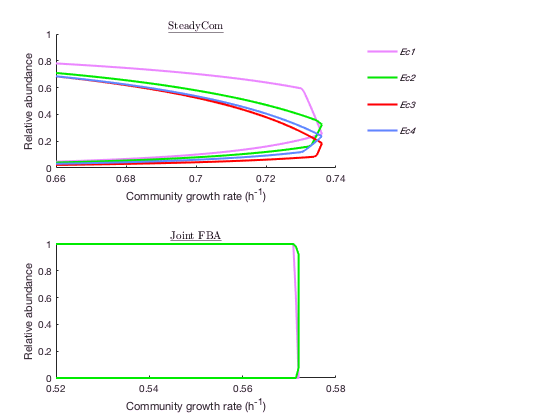

grComV = result.GRmax * options.optGRpercent / 100;  % vector of growth rates tested
lgLabel = {'{\itEc1 }';'{\itEc2 }';'{\itEc3 }';'{\itEc4 }'};
col = [235 135 255; 0 235 0; 255 0 0; 95 135 255 ]/255;  % color
f = figure;
% SteadyCom
subplot(2, 1, 1);
hold on
x = [grComV(:); flipud(grComV(:))];
for j = 1:4
    y = [fvaComMin(j, :), fliplr(fvaComMax(j, :))];
    p(j, 1) = plot(x(~isnan(y)), y(~isnan(y)), 'LineWidth', 2);
    p(j, 1).Color = col(j, :);
end
tl(1) = title('\underline{SteadyCom}', 'Interpreter', 'latex');
tl(1).Position = [0.7 1.01 0];
ax(1) = gca;
ax(1).XTick = 0.66:0.02:0.74;
ax(1).YTick = 0:0.2:1;
xlim([0.66 0.74])
ylim([0 1])

lg = legend(lgLabel);
lg.Box = 'off';
yl(1) = ylabel('Relative abundance');
xl(1) = xlabel('Community growth rate (h^{-1})');
% FBA
grFBAV = grFBA * optGRpercentFBA / 100;
x = [grFBAV(:); flipud(grFBAV(:))];
subplot(2, 1, 2);
hold on
% plot j=1:2 only because 3:4 overlap with 1:2
for j = 1:2
    y = [fvaFBAMin(j, :), fliplr(fvaFBAMax(j, :))] ./ x';
    % it is possible some values > 1 because the total biomass produced is
    % only bounded below when calling fluxVariability. Would be strictly
    % equal to 1 if sum(biomass) = optGRpercentFBA(jGr) * grFBA is constrained. Treat them as 1.
    y(y>1) = 1;
    p(j, 2)= plot(x(~isnan(y)), y(~isnan(y)), 'LineWidth', 2);
    p(j, 2).Color = col(j, :);
end
tl(2) = title('\underline{Joint FBA}', 'Interpreter', 'latex');
tl(2).Position = [0.55 1.01 0];
ax(2) = gca;
ax(2).XTick = 0.52:0.02:0.58;
ax(2).YTick = 0:0.2:1;
xlim([0.52 0.58])
ylim([0 1])
xl(2) = xlabel('Community growth rate (h^{-1})');
yl(2) = ylabel('Relative abundance');
ax(1).Position = [0.1 0.6 0.5 0.32];
ax(2).Position = [0.1 0.1 0.5 0.32];
lg.Position = [0.65 0.65 0.1 0.27];

The direct use of FVA compared to FVA under the SteadyCom framework gives very little information on the organism's abundance. The ranges for almost all growth rates span from 0 to 1. In contrast, `SteadyComFVA` returns results with the expected co-existence of all four mutants. When the growth rates get closer to the maximum, the ranges shrink to unique values.

## Analyze Pairwise Relationship Using SteadyComPOA

Now we would like to see at a given growth rate, how the abundance of an organism influences the abundance of another organism. We check this by iteratively fixing the abundance of an organism at a level (independent variable) and optimizing for the maximum and minimum allowable abundance of another organism (dependent variable). This is what `SteadyComPOA` does.

Set up the option structure and call `SteadyComPOA`. `Nstep` is an important parameter to designate how many intermediate steps are used or which values between the min and max values of the independent variable are used for optimizing the dependent variable. `savePOA` options must be supplied with a non-empty string or a default name will be used for saving the POA results. By default, the function analyzes all possible pairs in `options.rxnNameList`. To analyze only particular pairs, use `options.pairList`. See `help SteadyComPOA `for more details.

options.savePOA = ['POA' filesep 'EcCom'];  % directory and fila name for saving POA results
options.optGRpercent = [99 90 70 50];  % analyze at these percentages of max. growth rate
% Nstep is the number of intermediate steps that the independent variable will take different values
% or directly the vector of values, e.g. Nsetp = [0, 0.5, 1] implies fixing the independent variable at the minimum,
% 50% from the min to the max and the maximum value respectively to find the attainable range of the dependent variable.
% Here use small step sizes when getting close to either ends of the flux range
a = 0.001*(1000.^((0:14)/14));
options.Nstep = sort([a (1-a)]);
[POAtable, fluxRange, Stat, GRvector] = SteadyComPOA(EcCom, options);

Find maximum community growth rate..
Model feasible at maintenance. Time elapsed: 1 / 1 sec
Iter        LB   To test        UB  Time elapsed (iteration/total)
   1  0.000000  0.500000       Inf  0 / 1 sec
   2  0.500000  0.721279       Inf  6 / 8 sec
   3  0.721279  0.735372       Inf  0 / 8 sec
   4  0.735372  0.742726       Inf  0 / 8 sec
   5  0.735372  0.739049  0.742726  0 / 9 sec
   6  0.735372  0.737211  0.739049  0 / 9 sec
   7  0.735372  0.736291  0.737211  0 / 9 sec
   8  0.735372  0.735832  0.736291  0 / 10 sec
   9  0.735832  0.736062  0.736291  2 / 12 sec
  10  0.735832  0.735947  0.736062  0 / 12 sec
  11  0.735947  0.736004  0.736062  3 / 15 sec
  12  0.735947  0.735975  0.736004  0 / 15 sec
  13  0.735975  0.735990  0.736004  3 / 18 sec
  14  0.735990  0.735997  0.736004  0 / 19 sec
  15  0.735990  0.735993  0.735997  0 / 19 sec
  16  0.735990  0.735991  0.735993  1 / 20 sec
  17  0.735990  0.735991  0.735991  1 / 20 sec
Maximum community growth rate: 0.735991 (abs. err

POAtable is a *n*-by-*n* cell if there are *n* targets in `options.rxnNameList`. `POAtable{i, i}` is a *Nstep*-by-1-by-*Ngr* matrix where *Nstep *is the number of intermediate steps detemined by `options.Nstep` and *Ngr *is the number of growth rates analyzed. `POAtable{i, i}(:, :, k)` is the values at which the *i*-th target is fixed for the community growing at the growth rate `GRvector(k)`. POAtable{i, j} is a *Nstep*-by-2-by-*Ngr* matrix where `POAtable{i, j}(:, 1, k)` and `POAtable{i, j}(:, 2, k)` are respectively the min. and max. values of the *j*-th target when fixing the *i*-th target at the corresponding values in `POAtable{i, i}(:, :, k)`. `fluxRange `contains the min. and max. values for each target (found by calling `SteadyComFVA`). `Stat `is a *n*-by-*n-by-Ngr* structure array, each containing two fields: `*.cor`, the correlatiion coefficient between the max/min values of the dependent variable and the independent variable, and `*.r2`, the R-squred of linear regression. They are also outputed in the command window during computation. All the computed results are also saved in the folder 'POA' starting with the name 'EcCom', followed by 'GRxxxx' denoting the growth rate at which the analysis is performed.

Plot the results (see also Figure 3 in ref. [1]):

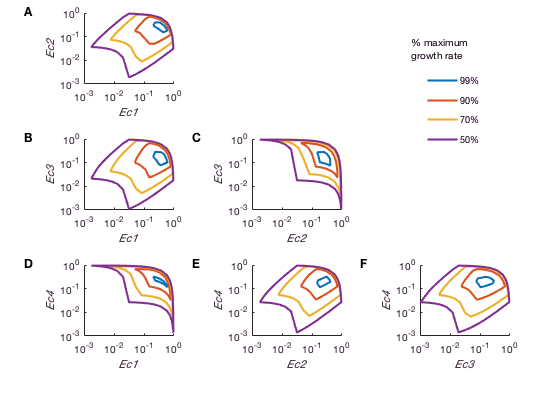

nSp = 4;
spLab = {'{\it Ec1 }';'{\it Ec2 }';'{\it Ec3 }';'{\it Ec4 }'};
mark = {'A', 'B', 'D', 'C', 'E', 'F'};
nPlot = 0;
for j = 1:nSp
    for k = 1:nSp
        if k > j
            nPlot = nPlot + 1;
            ax(j, k) = subplot(nSp-1, nSp-1, (k - 2) * (nSp - 1) + j);
            hold on
            for p = 1:size(POAtable{1, 1}, 3)
                x = [POAtable{j, j}(:, :, p);POAtable{j, j}(end:-1:1, :, p);...
                    POAtable{j, j}(1, 1, p)];
                y = [POAtable{j, k}(:, 1, p);POAtable{j, k}(end:-1:1, 2, p);...
                        POAtable{j, k}(1, 1, p)];
                plot(x(~isnan(y)), y(~isnan(y)), 'LineWidth', 2)
            end
            xlim([0.001 1])
            ylim([0.001 1])
            ax(j, k).XScale = 'log';
            ax(j, k).YScale = 'log';
            ax(j, k).XTick = [0.001 0.01 0.1 1];
            ax(j, k).YTick = [0.001 0.01 0.1 1];
            ax(j, k).YAxis.MinorTickValues=[];
            ax(j, k).XAxis.MinorTickValues=[];
            ax(j, k).TickLength = [0.03 0.01];
            xlabel(spLab{j});
            ylabel(spLab{k});
            tx(j, k) = text(10^(-5), 10^(0.1), mark{nPlot}, 'FontSize', 12, 'FontWeight', 'bold');
        end
    end
end
lg = legend(strcat(strtrim(cellstr(num2str(options.optGRpercent(:)))), '%'));
lg.Position = [0.7246 0.6380 0.1700 0.2015];
lg.Box='off';
subplot(3, 3, 3, 'visible', 'off');
t = text(0.2, 0.8, {'% maximum';'growth rate'});
for j = 1:nSp
    for k = 1:nSp
        if k>j
            ax(j, k).Position = [0.15 + (j - 1) * 0.3, 0.8 - (k - 2) * 0.3, 0.16, 0.17];
            ax(j, k).Color = 'none';
        end
    end
end

There are two patterns observed. The two pairs showing negative correlations, namely Ec1 vs Ec4 (panel D) and Ec2 vs Ec3 (panel C) are indeed competing for the same amino acids with each other (Ec1 and Ec4 competing for Lys and Met; Ec2 and Ec4 competing for Arg and Phe). Each of the other pairs showing positive correlations are indeed the cross feeding pairs, e.g., Ec1 and Ec2 (panel A) cross feeding on Arg and Lys. See ref. [1] for more detailed discussion.

## Parallelization and Timing

SteadyCom in general can be finished within 20 iterations, i.e. solving 20 LPs (usually faster if using Matlab fzero) for an accuracy of 1e-6 for the maximum community growth rate. The actual computation time depends on the size of the community metabolic network. The current `EcCom` model has 6971 metabolites and 9831 reactions. It took 18 seconds for a MacBook Pro with 2.5 GHz Intel Core i5, 4 GB memory running Matlab R2016b and Cplex 12.7.1.

Since the FVA and POA analysis can be time-consuming for large models with a large number of reactions to be analyzed, SteadyComFVA and SteadyComPOA support parrallelization using the Matlab Distributed Computing Toolbox (`parfor` for SteadyComFVA and `spmd` for SteadyComPOA). 

Test SteadyCom with 2 threads:

options.rxnNameList = EcCom.rxns(1:100);  % test FVA for the first 50 reactions
options.optGRpercent = 99;
options.algorithm = 1;
options.threads = 1;  % test single-thread computation first
options.verbFlag = 0;  % no verbose output
tic;
[minF1, maxF1] = SteadyComFVA(EcCom, options);  
t1 = toc;
if isempty(gcp('nocreate'))
    parpool(2)  % start a parallel pool
end
options.threads = 2;  % two threads (0 to use all available workers)
tic;
[minF2, maxF2] = SteadyComFVA(EcCom, options);  % test single-thread computation first

t2 = toc;
fprintf('Maximum difference between the two solutions: %.4e\n', max(max(abs(minF1 - minF2)), max(abs(maxF1 - maxF2))));

Maximum difference between the two solutions: 5.2591e-09


fprintf('\nSingle-thread computation: %.0f sec\nTwo-thread computation: %.0f sec\n', t1, t2);


Single-thread computation: 96 sec
Two-thread computation: 58 sec


If there are many reactions to be analyzed, use `options.saveFVA` to give a relative path for saving the intermediate results. Even though the computation is interrupted, by calling `SteadyComFVA` with the same `options.saveFVA`, the program will detect previously saved results and continued from there.

Test SteadyComPOA with 2 threads:

options.rxnNameList = EcCom.rxns(find(abs(result.flux) > 1e-2, 6));
options.savePOA = 'POA/EcComParallel';  % save with a new name
options.verbFlag = 3;
options.threads = 2;
options.Nstep = 5;  % smaller steps for quicker computation
tic;
[POAtable1, fluxRange1] = SteadyComPOA(EcCom, options);

Find maximum community growth rate..
Model feasible at maintenance. Time elapsed: 2 / 2 sec
Iter        LB   To test        UB  Time elapsed (iteration/total)
   1  0.000000  0.500000       Inf  0 / 2 sec
   2  0.500000  0.721279       Inf  6 / 8 sec
   3  0.721279  0.735372       Inf  0 / 8 sec
   4  0.735372  0.742726       Inf  0 / 9 sec
 
 Func-count    x          f(x)             Procedure
    2        0.735372  -0.000807615        initial
    3        0.735378   -0.00079987        interpolation
    4         0.73599  -1.26398e-06        interpolation
    5         0.73599  -1.26398e-06        interpolation
 
Zero found in the interval [0.735372, 0.742726]
Maximum community growth rate: 0.735990 (abs. error < 1e-06).	Time elapsed: 19 sec

FVA for 6 sets of fluxes/biomass at growth rate 0.728630 :

Thread 2:	33.33% finished. 2017-07-08 19:34:49
Thread 1:	33.33% finished. 2017-07-08 19:34:49
Thread 2:	66.67% finished. 2017-07-08 19:34:51
Thread 1:	66.67% finished. 2017-07-08 19:34:5

t3 = toc;

The parallelization code uses `spmd` and will redistribute jobs once any of the workers has finished to maximize the computational efficiency.

options.savePOA = 'POA/EcComSingeThread';  
options.threads = 1;
tic;
[POAtable2, fluxRange2] = SteadyComPOA(EcCom, options);

Find maximum community growth rate..
Model feasible at maintenance. Time elapsed: 1 / 1 sec
Iter        LB   To test        UB  Time elapsed (iteration/total)
   1  0.000000  0.500000       Inf  0 / 1 sec
   2  0.500000  0.721279       Inf  4 / 5 sec
   3  0.721279  0.735372       Inf  0 / 6 sec
   4  0.735372  0.742726       Inf  0 / 6 sec
 
 Func-count    x          f(x)             Procedure
    2        0.735372  -0.000807615        initial
    3        0.735378   -0.00079987        interpolation
    4         0.73599  -1.26398e-06        interpolation
    5         0.73599  -1.26398e-06        interpolation
 
Zero found in the interval [0.735372, 0.742726]
Maximum community growth rate: 0.735990 (abs. error < 1e-06).	Time elapsed: 12 sec

FVA for 6 sets of fluxes/biomass at growth rate 0.728630 :
  No	   %	      Name	      Min	      Max
   1	  17	Ec13HAD100	 0.052591	 0.217439
   2	  33	Ec13HAD120	 0.000000	 0.262936
   3	  50	Ec13HAD121	 0.022231	 0.202541
   4	  67	Ec13HAD140	 0

t4 = toc;
dev = 0;
for i = 1:size(POAtable1, 1)
    for j = i:size(POAtable1, 2)
        dev = max(max(max(abs(POAtable1{i, j} - POAtable2{i, j}))));
        dev = max(dev, max(max(abs(fluxRange1 - fluxRange2))));
    end
end
fprintf('Maximum difference between the two solutions: %.4e\n', dev);

Maximum difference between the two solutions: 1.3801e-10


fprintf('\nSingle-thread computation: %.0f sec\nTwo-thread computation: %.0f sec\n', t4, t3);


Single-thread computation: 769 sec
Two-thread computation: 908 sec


The advantage will be more significant for more targets to analyzed and more threads used. Similar to `SteadyComFVA`, `SteadyComPOA` also supports continuation from previously interrupted computation by calling with the same `options.savePOA`.

## REFERENCES

*[1] *Chan SHJ, Simons MN, Maranas CD (2017) SteadyCom: Predicting microbial abundances while ensuring community stability. PLoS Comput Biol 13(5): e1005539. https://doi.org/10.1371/journal.pcbi.1005539

*[2] *Khandelwal RA, Olivier BG, Röling WFM, Teusink B, Bruggeman FJ (2013) Community Flux Balance Analysis for Microbial Consortia at Balanced Growth. PLoS ONE 8(5): e64567. https://doi.org/10.1371/journal.pone.0064567